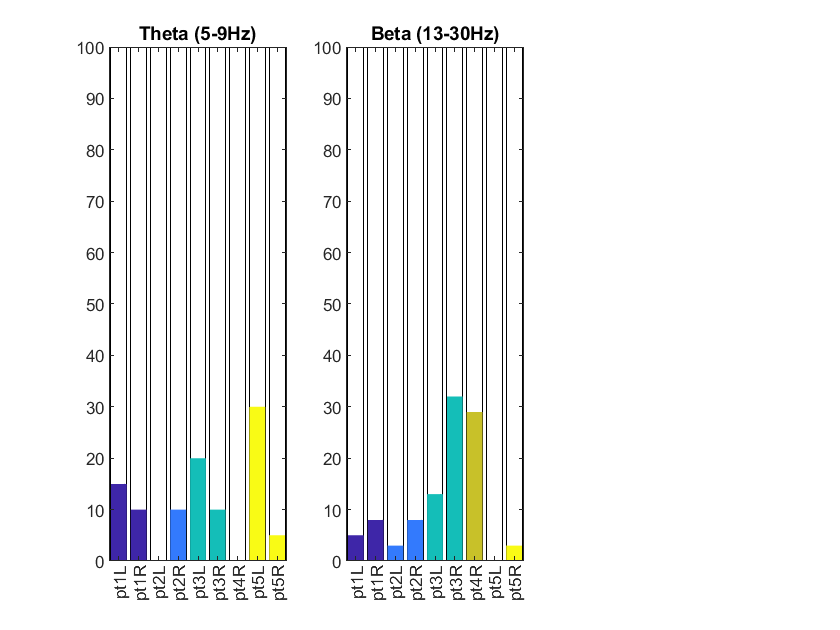

close all
t = tiledlayout(1,3);
nexttile 
data = readtable("thetataballcontact_new.xlsx"); 
data2 = data(contains(data.Group, 'minus'), :); %all data 
data3 = data2(data2.Sig == 1, :); %anything significant 
indicies = find(data2.Sig == 1); 

sig_amt = zeros(9,1); 
pt_list = unique(data2.Patients); 
for i = 1:9
    %count all the times that a patient appears in the sig difference list 
sig_amt(i) = height(data3(contains(data3.Patients, pt_list{i}, "IgnoreCase", true), :)); 
end 

%old code, not sure why it's 18 
%sig_amt = round(100*(sig_amt/18)); 
%new code, normalize by the total amount of sig differences
%final result should sum to 100 
sig_amt = round(100*(sig_amt/(sum(sig_amt))));

cmap = parula; 
cmapindex = round(linspace(1,256,5)); %gets 5 equally spaced poitns within perula 
p1color = cmap(cmapindex(1), :); %gets the RGB for the first color from cmapindex 
p2color = cmap(cmapindex(2), :);  
p3color = cmap(cmapindex(3), :);  
p4color = cmap(cmapindex(4), :);  
p5color = cmap(cmapindex(5), :);  

%total of 18 instances for each thing 
x = categorical(replace(pt_list, {'LEFT', 'RIGHT'}, {'L', 'R'})); 
%x = categorical({'A', 'B', 'C', 'D', 'E', 'F', 'G', 'H', 'I'}); 
y = repmat(100, 1, 9); 
b1 = bar(x,y); %make the background 
b1.FaceColor = [ 1 1 1]; 
y1 = repmat(10, 1, 9); 
hold on 
b =bar(x, sig_amt);
b.FaceColor = 'flat';
%PT1
b.CData(1,:) = p1color; 
b.CData(2,:) = p1color; 
%PT2
b.CData(3,:) = p2color; 
b.CData(4,:) = p2color; 
%PT3
b.CData(5,:) = p3color; 
b.CData(6,:) = p3color; 
%PT4
b.CData(7,:) = p4color; 
%PT5
b.CData(8,:) = p5color; 
b.CData(9,:) = p5color;  
b.LineStyle = 'none';
title("Theta (5-9Hz)")

percent_sig_theta = round(100*(height(data3) / height(data2))); 

%%%%%%%%%%%%%%%%%%%%%%Beta%%%%%%%%%%%%%%%%%%%
nexttile 
data = readtable("betataballcontact_new.xlsx"); 
data2 = data(contains(data.Group, 'minus'), :); %all data 
data3 = data2(data2.Sig == 1, :); %anything significant 
indicies = find(data2.Sig == 1); 

sig_amt = zeros(9,1); 
pt_list = unique(data2.Patients); 
for i = 1:9
sig_amt(i) = height(data3(contains(data3.Patients, pt_list{i}, "IgnoreCase", true), :)); 
end 

%old code, not sure why it's 18 
%sig_amt = round(100*(sig_amt/18)); 
%new code, normalize by the total amount of sig differences
%final result should sum to 100 
sig_amt = round(100*(sig_amt/(sum(sig_amt))));


cmap = parula; 
cmapindex = round(linspace(1,256,5)); %gets 5 equally spaced poitns within perula 
p1color = cmap(cmapindex(1), :); %gets the RGB for the first color from cmapindex 
p2color = cmap(cmapindex(2), :);  
p3color = cmap(cmapindex(3), :);  
p4color = cmap(cmapindex(4), :);  
p5color = cmap(cmapindex(5), :);  

%total of 18 instances for each thing 
x = categorical(replace(pt_list, {'LEFT', 'RIGHT'}, {'L', 'R'})); 
%x = categorical({'A', 'B', 'C', 'D', 'E', 'F', 'G', 'H', 'I'}); 
y = repmat(100, 1, 9); 
b1 = bar(x,y); %make the background 
b1.FaceColor = [ 1 1 1]; 
y1 = repmat(10, 1, 9); 
hold on 
b =bar(x, sig_amt);
b.FaceColor = 'flat';
%PT1
b.CData(1,:) = p1color; 
b.CData(2,:) = p1color; 
%PT2
b.CData(3,:) = p2color; 
b.CData(4,:) = p2color; 
%PT3
b.CData(5,:) = p3color; 
b.CData(6,:) = p3color; 
%PT4
b.CData(7,:) = p4color; 
%PT5
b.CData(8,:) = p5color; 
b.CData(9,:) = p5color;  
b.LineStyle = 'none';
title("Beta (13-30Hz)") 


percent_sig_beta = round(100*(height(data3) / height(data2))); 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%Gamma%%%%%%%%%%%%%%%%%%%% 
nexttile 
data = readtable("gammataballcontact_new.xlsx"); 
data2 = data(contains(data.Group, 'minus'), :); %all data 
data3 = data2(data2.Sig == 1, :); %anything significant 
indicies = find(data2.Sig == 1); 

sig_amt = zeros(9,1); 
pt_list = unique(data2.Patients); 
for i = 1:9
sig_amt(i) = height(data3(contains(data3.Patients, pt_list{i}, "IgnoreCase", true), :)); 
end 

%old code, not sure why it's 18 
%sig_amt = round(100*(sig_amt/18)); 
%new code, normalize by the total amount of sig differences
%final result should sum to 100 
sig_amt = round(100*(sig_amt/(sum(sig_amt))));


cmap = parula; 
cmapindex = round(linspace(1,256,5)); %gets 5 equally spaced poitns within perula 
p1color = cmap(cmapindex(1), :); %gets the RGB for the first color from cmapindex 
p2color = cmap(cmapindex(2), :);  
p3color = cmap(cmapindex(3), :);  
p4color = cmap(cmapindex(4), :);  
p5color = cmap(cmapindex(5), :);  

percent_sig_gamma = round(100*(height(data3) / height(data2))); 

%total of 18 instances for each thing 
x = categorical(replace(pt_list, {'LEFT', 'RIGHT'}, {'L', 'R'})); 
%x = categorical({'A', 'B', 'C', 'D', 'E', 'F', 'G', 'H', 'I'}); 
y = repmat(100, 1, 9); 
b1 = bar(x,y); %make the background 
b1.FaceColor = [ 1 1 1]; 
y1 = repmat(10, 1, 9); 
hold on 
b =bar(x, sig_amt);
b.FaceColor = 'flat';
%PT1
b.CData(1,:) = p1color; 
b.CData(2,:) = p1color; 
%PT2
b.CData(3,:) = p2color; 
b.CData(4,:) = p2color; 
%PT3
b.CData(5,:) = p3color; 
b.CData(6,:) = p3color; 
%PT4
b.CData(7,:) = p4color; 
%PT5
b.CData(8,:) = p5color; 
b.CData(9,:) = p5color;  
b.LineStyle = 'none';
title("Gamma (>30Hz)")

title(t,'Fraction of Significantly Different Runs Per Patient and Hemisphere'); 
xlabel(t, "Patient and Hemisphere")
ylabel(t, "Fraction of Significant Differences")
t.TileSpacing = 'loose'